clear
clc
close all

% Loading in functions and generating the dataset
load("Data_Problem1_regression.mat");
Ts = [T1 T2 T3 T4 T5];
nums = [7; 7; 5; 3; 2];
Tnew = sum(Ts*nums,2)/(sum(nums));
dataset = [X1 X2 Tnew];

% Generating random training, validation, and test sets
indices = [1:13600];
full_ind = datasample(indices,3000,2,"Replace",false);

train_ind = full_ind(:,1:1000);
test_ind = full_ind(:,1001:2000);
val_ind = full_ind(:,2001:3000);
train_set = dataset(train_ind, :);
val_set = dataset(val_ind, :);
test_set = dataset(test_ind, :);

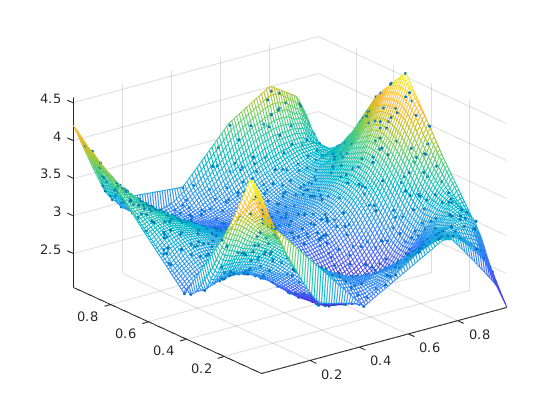

%plotting the training set
train_X1 = train_set(:,1);
train_X2 = train_set(:,2);
train_T = train_set(:,3);

xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(train_X1,train_X2,train_T);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(train_X1,train_X2,train_T,'.');

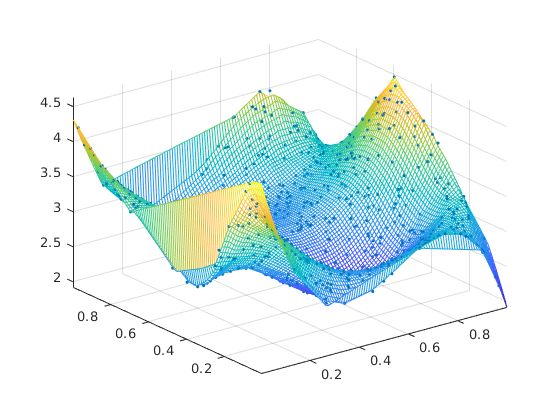

%Plotting the test set
test_X1 = test_set(:,1);
test_X2 = test_set(:,2);
test_T = test_set(:,3);

xlin = linspace(min(dataset(:,1)), max(dataset(:,1)));
ylin = linspace(min(dataset(:,2)), max(dataset(:,2)));
[X,Y] = meshgrid(xlin,ylin);

f = scatteredInterpolant(test_X1,test_X2,test_T);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight; hold on
plot3(test_X1,test_X2,test_T,'.');

Build and train your feedforward Neural Network: use the training and validation sets. Build the ANN with 2 inputs and 1 output. Select a suitable model for the problem (number of hidden layers, number of neurons on each hidden layer). Select the learning algorithm and the transfer function that may work best for this problem. Motivate your decisions. When you try different networks, clearly say at the end which one you would select as the best for this problem and why.

% Building and training the network
lm_net = fitnet([30 30], 'trainlm');
lm_net.trainParam.epochs=400;
lm_net.numInputs = 2;
lm_net.inputConnect(1,1) = 1;
lm_net.inputConnect(1,2) = 1;
lm_net.inputs{1}.size = 1;
lm_net.inputs{2}.size = 1;
lm_net.divideFcn = 'divideind';
lm_net.divideParam.trainInd = train_ind;
lm_net.divideParam.valInd = val_ind;
lm_net.divideParam.testInd = test_ind;

X = {X1';X2'};
lm_net = configure(lm_net,X);
[lm_net, lm_tr] = train(lm_net,X,Tnew');

figure
plotperform(lm_tr);

% Evaluating network on original inputs
t = cell2mat(lm_net(X))';

X1lin = linspace(min(X1), max(X1));
X2lin = linspace(min(X2), max(X2));

[X,Y] = meshgrid(X1lin,X2lin);

f = scatteredInterpolant(X1,X2,t);
Z = f(X,Y);

figure
mesh(X,Y,Z)
axis tight;

Tuning the network hyperparameters:

First will tune the architecture itself: number of neurons and number of layers

Then I will experiment with different activation functions.

Lastly I will look at the number of epochs.

neurons = 60;
test_errors = zeros(10,4);

for j=1:10
    for i=1:4
        layers = zeros(1,i);
        layers(1,:) = round(neurons/i);
        
        % Building and training the network
        net = fitnet(layers, 'trainlm');
        net.trainParam.epochs=100;
        net.numInputs = 2;
        net.inputConnect(1,1) = 1;
        net.inputConnect(1,2) = 1;
        net.inputs{1}.size = 1;
        net.inputs{2}.size = 1;
        net.divideFcn = 'divideind';
        net.divideParam.trainInd = train_ind;
        net.divideParam.valInd = val_ind;
        net.divideParam.testInd = test_ind;
        
        X = {X1';X2'};
        net = configure(net,X);
        [net, tr] = train(net,X,Tnew');
        test_errors(j,i) = tr.best_tperf;
    end
end
layer_errors = mean(test_errors)

for j=1:10
    
    %initialising networks
    br_net = fitnet(30, 'trainbr');
    lm_net = fitnet(30, 'trainlm');
    nets = {br_net, lm_net};
    
    for i = 1:length(nets)                        
        nets{i}.iw{1,1}=br_net.iw{1,1}; %set the same weights and biases for the networks 
        nets{i}.lw{2,1}=br_net.lw{2,1};
        
        nets{i}.b{1}=br_net.b{1};
        nets{i}.b{2}=br_net.b{2};  
    end
    
    %training networks with 100 epochs
    br_net.trainParam.epochs=100;
    lm_net.trainParam.epochs=100;
    
    [br_net, br_tr] = train(br_net, x, t);
    [lm_net, lm_tr] = train(lm_net, x, t);
    
    %estimating targets using trained networks
    y_br = br_net(x);
    y_lm = lm_net(x);
    
    %assessing performances of networks with MSE
    br_test_perf = br_tr.best_tperf;
    lm_test_perf = lm_tr.best_tperf;
    test_perfs = [br_test_perf lm_test_perf];
    mse_100epoch(j,:) = test_perfs;
    
    %regression performance of networks
    r_br = abs(regression(y_br,t));
    r_lm = abs(regression(y_lm,t));
    regress_100 = [r_br r_lm];
    regress_100epoch(j,:) = regress_100;
    
    
    epoch_br = br_tr.best_epoch;
    epoch_lm = lm_tr.best_epoch;
    best_epochs = [epoch_br epoch_lm];
    best_epoch_100(j,:) = best_epochs;
end

average_regress = mean(regress_100epoch, 1);
average_mse = mean(mse_100epoch, 1);
average_epochs = mean(best_epoch_100, 1);

%plotting
figure
subplot(2,2,1);
plot(x,t,'kx',x, y_br,x,y_lm); % plot the sine function and the output of the networks
title('100 epochs');
legend('target','trainbr','trainlm','Location','northwest');

subplot(2,2,2);
b = bar(average_regress,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
ylim([0 1.1]);
title('Regression 100 epochs');

subplot(2,2,3);
b = bar(average_mse,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Test MSE 100 epochs');

subplot(2,2,4);
b = bar(average_epochs,'FaceColor','flat');
b.CData =  newcolours;
set(gca, 'xticklabel',algorithm);
xtickangle(45);
title('Average Final Epoch 100');

colororder(newcolours);